# [ARX Time Series Model](https://apmonitor.com/pds/index.php/Main/ARXTimeSeries)

**Note: Follwing module will require the **[**System Identification Toolbox**](https://www.mathworks.com/products/sysid.html)** as well as the download of the python file "arx_python.py" to your current working directory **

An ARX model is a combination of an autoregressive model (AR) and an exogenous input model (X). It is used to represent the dynamics of a system and is commonly used in control engineering to model and analyze dynamic systems.

An autoregressive model is a type of statistical model that represents a time series as a linear combination of its past values and a stochastic process. It is represented by the following equation:


$$y\left(t\right)=c+a_1 y\left(t-1\right)+a_2 y\left(t-2\right)+\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp +a_p y\left(t-p\right)+e\left(t\right)$$


where *y(t)* is the value of the time series at time *t*, *c* is a constant term, *a**1*, *a**2*, ..., *a**p* are the autoregressive coefficients, *y(t-1)*, *y(t-2)*, ..., *y(t-p)* are the past values of the time series, and *e(t)* is a random error term.

An exogenous input model represents a time series as a linear combination of its past values and a set of exogenous (i.e., external) input variables. It is represented by the following equation:


$$y\left(t\right)=c+b_1 u_1 \left(t\right)+b_2 u_2 \left(t\right)+\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp +b_q u_q \left(t\right)+e\left(t\right)$$


where *y(t)* is the value of the time series at time *t*, *c* is a constant term, *u**1**(t)*, *u**2**(t)*, ..., *u**q**(t)* are the exogenous input variables, and *b**1*, *b**2*, ..., *b**q* are the coefficients that capture the relationship between the input variables and the output.

An ARX model is a combination of an AR model and an X model, and it is represented by the following equation:


$$y\left(t\right)=c+a_1 y\left(t-1\right)+a_2 y\left(t-2\right)+\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp +a_p y\left(t-p\right)+b_1 u_1 \left(t\right)+b_2 u_2 \left(t\right)+\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp +b_q u_q \left(t\right)+e\left(t\right)$$


ARX time series models are a linear representation of a dynamic system in discrete time. Putting a model into ARX form is the basis for many methods in process dynamics and control analysis. Below is the time series model with a single input and single output with *k* as an index that refers to the time step.


$$y_{k+1} =\sum_{i=1}^{n_a } a_i y_{k-1+1} +\sum_{i=1}^{n_b } b_i u_{k-1+1}$$


With *n**a*=3, *n**b*=2, *n**u*=1, and *n**y*=1 the time series model is:


$$y_{k+1} =a_1 y_k +a_2 y_{k-1} +a_3 y_{k-2} +b_1 u_k +b_2 u_{k-1}$$


There may also be multiple inputs and multiple outputs such as when *n**a*=1, *n**b*=1, *n**u*=2, and *n**y*=2.


$${\textrm{y1}}_{k+1} =a_{1,1} {\;\;\textrm{y1}}_k \;+b_{1,1\;} {\textrm{u1}}_k +b_{1,2} \;{\textrm{u2}}_k$$



$${\textrm{y2}}_{k+1} =a_{1,2} {\;\textrm{y2}}_k +b_{2,1} \;{\textrm{u1}}_k +b_{2,2\;} {\textrm{u2}}_k$$


Time series models are used for identification and advanced control. It has been in use in the process industries such as chemical plants and oil refineries since the 1980s. Model predictive controllers rely on dynamic models of the process, most often linear empirical models obtained by system identification.

## System Identification Toolbox Method 

MATLAB already has the capability to create ARX models. Such functions are contained within the System Identification Toolbox, which should be downloaded for this module. Before the model can be made, certain coefficents should be created, signifying the coefficents of the equations which the ARX model will be based upon. Other matricies and coefficents must also be specified, as seen in the code below.

%%%% Create coefficents for the ARX model  
A = cell(2,2); 		

%%% model with independent outputs
A{1,1} = [1 -0.36788 -0.36788];	
A{1,2} = 0;
    
%%% Switched a_i's
A{2,1} = 0; 	
A{2,2} = [1 -0.223 0.136];

B = cell(2,2);
	
B{2,1} = [0.18964];
B{1,1} = [0.63212];
B{2,2} = [1.26420];
B{1,2} = [0.31606];

%%% Create Polynomials using created coefficents 
sys0 = idpoly(A,B)

sys0 =
Discrete-time ARX model:                                   
  Model for output number 1: A(z)y_1(t) = B(z)u(t) + e_1(t)
    A(z) = 1 - 0.3679 z^-1 - 0.3679 z^-2                   
                                                           
    B1(z) = 0.6321                                         
                                                           
    B2(z) = 0.3161                                         
                                                           
  Model for output number 2: A(z)y_2(t) = B(z)u(t) + e_2(t)
    A(z) = 1 - 0.223 z^-1 + 0.136 z^-2                     
                                                           
    B1(z) = 0.1896                                         
                                                           
    B2(z) = 1.264                                          
                                                           
Sample time: unspecified
  
Parameterization:
   Polynomial orders:   na=[2 0;0 2]   nb=[1 1;


%%%%Initialize matrix for input and output storage
u1 = zeros(20,1)   

u1 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


u1(6:end) = 3

u1 =      0
     0
     0
     0
     0
     3
     3
     3
     3
     3



u2 = zeros(20,1)

u2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


u2(11:end) = 5

u2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



u = [u1 u2]

u =      0     0
     0     0
     0     0
     0     0
     0     0
     3     0
     3     0
     3     0
     3     0
     3     0


y1 = sim(sys0,u)    

y1 =          0         0
         0         0
         0         0
         0         0
         0         0
    1.8964    0.5689
    2.5940    0.6958
    3.5483    0.6467
    4.1560    0.6185
    4.7306    0.6189


%%%% system identification parameters
na = [2 0;0 2] %% output coefficients

na =      2     0
     0     2


nb = [1 1;1 1] %% input coefficients

nb =      1     1
     1     1


nk = [0 0;0 0]

nk =      0     0
     0     0



%%%%% Create and populate ARX model
sys_arx = arx(u,y1,[na nb nk])

sys_arx =
Discrete-time ARX model:                               
  Model for output "y1": A(z)y_1(t) = B(z)u(t) + e_1(t)
    A(z) = 1 - 0.3679 z^-1 - 0.3679 z^-2               
                                                       
    B1(z) = 0.6321                                     
                                                       
    B2(z) = 0.3161                                     
                                                       
  Model for output "y2": A(z)y_2(t) = B(z)u(t) + e_2(t)
    A(z) = 1 - 0.223 z^-1 + 0.136 z^-2                 
                                                       
    B1(z) = 0.1896                                     
                                                       
    B2(z) = 1.264                                      
                                                       
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=[2 0;0 2]   nb=[1 1;1 1]   nk=[0 0;0 0]
   Number of free coefficients: 8
   Us

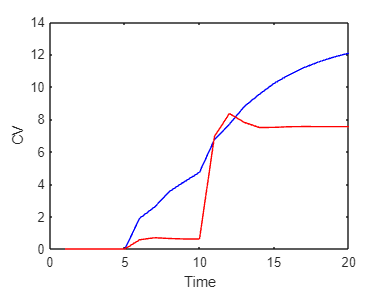


%%%% Plot arx model against created
%%%% using now populated Y vector and plotting against time
plot(y1(:,1),'b-')
hold all

%%% Graphing "CV" (Control Variable)
plot(y1(:,2),'r-')
xlabel("Time")
ylabel("CV")
hold off

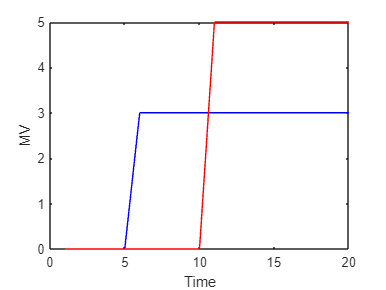


%%% Graphing "MV" (Manipulated Variable) 
plot(u1,'b-')
hold all
plot(u2,'r-')
xlabel("Time")
ylabel("MV")

## Utilizing Python Gekko Package

The GEKKO package with Python also makes it easy to do ARX models. Fortunately, MATLAB has the capability to run Python modules and code through its coding platform. If you have not already, install Python, examine the python file "arx_python.py" and run the following code to see its performance. 

Note: Python will need to be installed on your machine to run the following code. For installation information, please consult the links "Further Reading".

%% Check box to run python
runPython = true

runPython = logical
   1



if runPython
    import pip.*
    py.pip.main(py.list({'install','gekko'}))
    terminate(pyenv)
    pyStr = pyenv("ExecutionMode","OutOfProcess");
    pyTCL = fullfile(pyStr.Home, 'tcl', 'tcl8.6');
    pyTK = fullfile(pyStr.Home, 'tcl', 'tk8.6');
    setenv('TCL_LIBRARY', pyTCL);
    setenv('TK_LIBRARY', pyTK);
    pyrunfile('arx_python.py')
end

Please see https://github.com/pypa/pip/issues/5599 for advice on fixing the underlying issue.
To avoid this problem you can invoke Python with '-m pip' instead of running pip directly.


ans =   Python int with properties:

    denominator: [1×1 py.int]
           imag: [1×1 py.int]
      numerator: [1×1 py.int]
           real: [1×1 py.int]

    0


 ----------------------------------------------------------------
 APMonitor, Version 1.0.0
 APMonitor Optimization Suite
 ----------------------------------------------------------------
 
 
 --------- APM Model Size ------------
 Each time step contains
   Objects      :  1
   Constants    :  0
   Variables    :  4
   Intermediates:  0
   Connections  :  4
   Equations    :  0
   Residuals    :  0
 
 Number of state variables:    80
 Number of total equations: -  80
 Number of slack variables: -  0
 ---------------------------------------
 Degrees of freedom       :    0
 
 **********************************************
 Dynamic Simulation with Interior Point Solver
 **********************************************
  
  
 Info: Exact Hessian

******************************************************************************
This program contains Ipopt, a library for large-scale nonlinear optimization.
 Ipopt is released as open source code under the Eclipse Public License (EPL).
         F

## Further Reading

GEKKO python package documentation

[https://gekko.readthedocs.io/en/latest/](https://gekko.readthedocs.io/en/latest/)

Python Download from official Python website

[https://www.python.org/downloads/](https://www.python.org/downloads/)

Checking Python Compatibility with MATLAB 

[https://www.mathworks.com/support/requirements/python-compatibility.html](https://www.mathworks.com/support/requirements/python-compatibility.html) 

Python integration with MATLAB

[https://www.mathworks.com/help/matlab/call-python-libraries.html](https://www.mathworks.com/help/matlab/call-python-libraries.html)

Additional information on adding Python to "Path" in personal computer (Note: this step is sometimes necessary for MATLAB to recognize the proper source of Python on your machine)

[https://realpython.com/add-python-to-path/](https://realpython.com/add-python-to-path/)

Note: Python module "arx_python.py" will only run with Python downloaded from through the Python website and not through third party app stores (ex. Windows Store)